# Projeto4: 2DPCA Bidirecional

## UFAM/PPGEE/Apredizado de Máquina 2021-1

Carlos Fonseca, Willian Guerreiro


clc
clear all;
close all;
load ORL_FaceDataSet;  % ATT Face Dataset com 40 indivíduos (classes) e 10 amostras de cada
A=double(ORL_FaceDataSet);

 
Num_Class = 40;
No_SampleClass = 10;
DIM = 10;    % Qtde de Autovetores (DIM: 1 a n)

%  Definição do Conjunto de Treinamento
%  ------------------------------------
No_TrainSamples =  7;
No_TestSamples  =  3;

[TrainData, TestData]    = Train_Test(A,No_SampleClass,No_TrainSamples,No_TestSamples);
[m,n,TotalTrainSamples]  = size(TrainData);
% m = 112
% n =  92
% TotalTrainSamples: 200

%  Definição do Conjunto de Testes
[m1,n1,TotalTestSamples] = size(TestData);
[TrainLabel,TestLabel]   = LebelSamples(Num_Class, No_TrainSamples, No_TestSamples);

% m1 = 112
% n1 =  92
% TotalTestSamples: 200


% Cálculo da Matriz de Covariancia (Projeção Horizontal)
% Gh = 1/n * SUM (Ai - Mean(A))'*(Ai - Mean(A)), i = 1:n
%-----------------------------------------------------------------------------
TrainMean = mean(TrainData,3); % Média do conjunto de treinamento na dimensão "z"
Gh=zeros([ n n]);

% TrainData é um conjunto de 200 imagens de tamanho 'mxn':
% m = 112
% n =  92

for i = 1:TotalTrainSamples
    Temp = TrainData(:,:,i) - TrainMean; % (Ai - Mean(A))
    Gh = Gh + Temp'*Temp;                % (Ai - Mean(A))'*(Ai - Mean(A))
end

Gh=Gh/TotalTrainSamples;                 % fator 1/N, N: 200
%Gh é n x n:  92 x 92 

% Cálculo da Matriz de Dispersão Vertical
% Gv = 1/n * SUM (Ai - Mean(A))*(Ai - Mean(A))', i = 1:n
%-----------------------------------------------------------------------------
TrainMean = mean(TrainData,3); % Média do conjunto de treinamento na dimensão "z"
Gv=zeros([ m m]);

for i = 1:TotalTrainSamples              % TotalTrainSamples : 200
    Temp = TrainData(:,:,i) - TrainMean; % (Ai - Mean(A)): m x n
    Gv = Gv + Temp*Temp';                % (Ai - Mean(A))'*(Ai - Mean(A)): (m x n) * (n x m): m x m
end

Gv=Gv/TotalTrainSamples;                 % fator 1/N
%Gv é m x m:  112 x 112 

%Redução de dimensionalidade com 2DLDA_BI

[U, V] = R_2DLDA_BI('ORL');

  Columns 1 through 11

    5.3805         0         0         0         0         0         0         0         0         0         0
         0    4.1469         0         0         0         0         0         0         0         0         0
         0         0    1.5894         0         0         0         0         0         0         0         0
         0         0         0    1.0313         0         0         0         0         0         0         0
         0         0         0         0    0.8817         0         0         0         0         0         0
         0         0         0         0         0    0.7046         0         0         0         0         0
         0         0         0         0         0         0    0.6721         0         0         0         0
         0         0         0         0         0         0         0    0.5188         0         0         0
         0         0         0         0         0         0         0         0    0.41



% Matriz de Projeção Horizontal U --> EigVect_H
% Maiores "q" Autovalores e Autovetores de Gh ("q" = DIM)
%----------------------------------------------
[EigVect1,EigVal1] = eig_decomp(Gh);
EigVect_H          = EigVect1(:,1:DIM);
% U = EigVect_H = n x q, n: 92 e q = DIM

% Matriz de Projeção Vertical V --> EigVect_V
% Maiores "q" Autovalores e Autovetores de Gh ("q" = DIM)
%----------------------------------------------
[EigVect1,EigVal1] = eig_decomp(Gv);
EigVect_V          = EigVect1(:,1:DIM); 
% V = EigVect_V = m x r, m: 112 e r = DIM

% Calculo das Imagens Projetadas do Cj. Treinamento
% Ap = V' * A * U (Ap: imagem projetada, A: imagem original)
% Ap = (r x m) * (m x n) * (n x q) = (r x m) * (m x q) = r x q
% ----------------------------------------------------------------------------------

for i = 1:TotalTrainSamples   
    %Ytrain(:,:,i) = EigVect_V' * TrainData(:,:,i) * EigVect_H; % Ap = V' * A * U
    Ytrain(:,:,i) = V' * TrainData(:,:,i) * U; % Ap = V' * A * U
end
% YTrain = Ap --> (r x q) = (DIM x DIM) = (10 x 10)


% Reconhecimento das Faces com o Conjunto de Teste
% 
%----------------------------------------------------
TestResult = zeros(TotalTestSamples,1);

for i=1:TotalTestSamples
    
    %Ytest(:,:,i) = EigVect_V' * TestData(:,:,i) * EigVect_H; 
    Ytest(:,:,i) = V' * TestData(:,:,i) * U;
end

% Implementação do Perceptron Multicamadas para Classificação
% e Reconhecimento das Faces
% Arquitetura da Rede: 100 x 10 x 10 x 40
% Entrada: vetor com 100 características: Imagens Proj. (PCA) de 10x10
% Saída  : Um vetor com os valores preditos para cada um dos indivíduos
% 1o. approach: y = '1' para o indivíduo reconhecido, y = '0' para os demais
% 2o. approach: y = densidade de probabilidade [0 a 1] para a semelhança
% entre a entrada e os 40 elementos possíveis na saída
% ---------------------------------------------------------------------
%
%  Funções do Toolbox do Matlab
%  
%  net = feedforwardnet(hiddenSizes,trainFcn)
% 
%  hiddenSizes: [10 10], 2 camadas de tamanho 10
%  
%  trainFcn: 
%  1) 'traingd'  :	Gradient Descent
%  2) 'traingdm' :  Gradient Descent with Momentum
%
%  net: é a representação da rede construída
%
%  Treinamento da Rede
%
%  net = train(net, xtrain, ytrain);
%  view(net); visualização da rede treinada
%   


   %net = patternnet([10 10]); % condição que alcancou 91%
   net = patternnet([20], 'trainscg');
   %trainscg
   %net = feedforwardnet([20],'traincgf');
   net.layers{1}.transferFcn = 'poslin';
   net.layers{2}.transferFcn = 'softmax';
   
   t = zeros(Num_Class,1);
   
   for i = 1:TotalTrainSamples
    B = Ytrain(:,:,i);
    x = B(:); % converte uma matriz para um vetor coluna
    YTrainVector(:,i) = x;
    tVector(:,i) = t;
    tVector(TrainLabel(i),i) = 1;
   
   end
   
   
    % Alcancou 87% de acerto
    % ----------------------
    
    net.trainParam.epochs = 2000;
    net.trainParam.goal = 1e-6; 
    net.trainParam.min_grad = 1e-6;
    net.trainParam.max_fail = 40;
   

    %YTrainVector_Norm = normalize(YTrainVector);   
    YTrainVector_Norm = YTrainVector;
    %net  = train(net, YTrainVector_Norm, tVector);
    net  = trainbr(net, YTrainVector_Norm, tVector);

    
    view(net);

%     net.trainParam.epochs = 1000;
%     net.trainParam.goal = 1e-7; 
%     net.trainParam.min_grad = 1e-7;
%     net.trainParam.max_fail = 200;
%     YTrainVector_Norm = normalize(YTrainVector);   
%     net  = train(net, YTrainVector_Norm, tVector);

   
   % Testando a Classificação
   
   t = zeros(Num_Class,1);
   for i = 1:TotalTestSamples
    B = Ytest(:,:,i);
    x = B(:); % converte uma matriz para um vetor coluna
    YTestVector(:,i) = x;
    tTestVector(:,i) = t;
    tTestVector(TestLabel(i),i) = 1;
   end

     
   %YTestVector_Norm = normalize(YTestVector);   
   YTestVector_Norm = YTestVector;
   y_pred = net(YTestVector_Norm(:,:));
   
   classes = vec2ind(y_pred);
   classes_reais = vec2ind(tTestVector);
   
   Result = (classes_reais == classes);  
   
   %Result = '1' para os acertos (TestResult = TestLabel)
 
   CorrectRate = 100*(sum(Result/TotalTestSamples))

CorrectRate = 93.3333

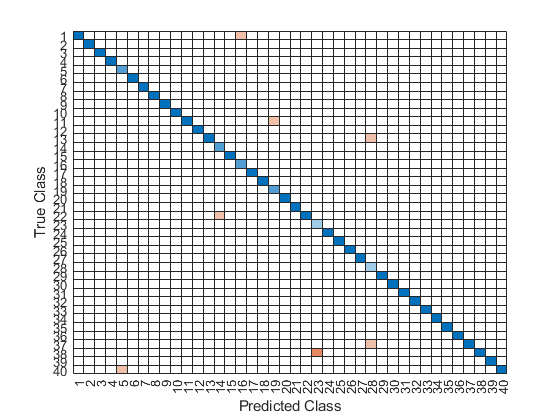

   % Índice de Acerto 
   
   perf = perform(net,y_pred,tTestVector);
    
   cm = confusionchart(classes,classes_reais);